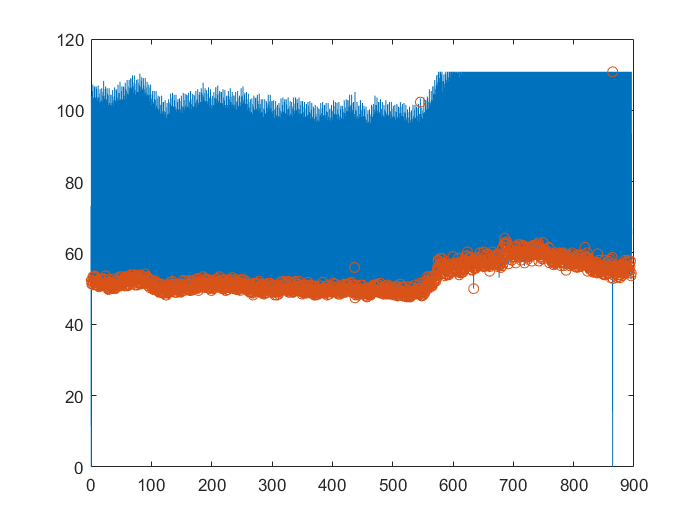

clearvars 
file = '3000063_0019';
%file = '3000714_0002';

annFolder = '../physionet.org/abp_ann/';
dataFolder = '../physionet.org/textdata/';

locOfBeats = cell2mat(textscan(...
    fopen([annFolder file '_abp.txt']), ...
    '%*s %d %*s %*d %*d %*d'));

data = cell2mat(textscan( fopen([dataFolder file '.txt']), ...
         '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));

plot(data(:,1), data(:,2))
hold on
scatter(data(locOfBeats,1), data(locOfBeats,2))
hold off

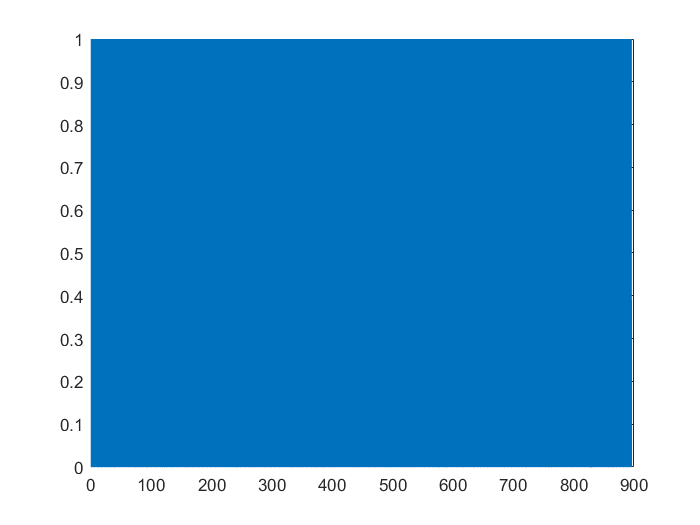

beatLocs = zeros(length(data),1);
beatLocs(locOfBeats) = 1;

% diffLocs = zeros(length(locOfBeats),1);
% diffLocs(diff(locOfBeats) < 150) = 1;
% 
% plot(data(locOfBeats,1),diffLocs);

plot(data(:,1), beatLocs);

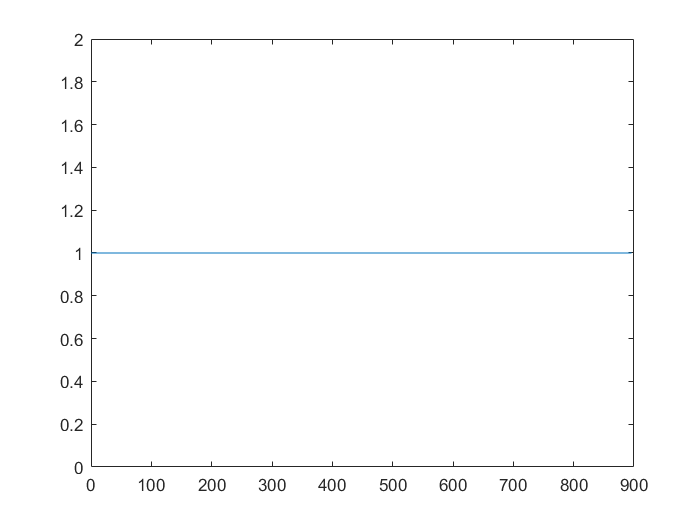


plot(data(:,1), movmax(beatLocs,[120 120]))
ylim([0 2])